# 2. Heat Transfer -thermalProperties

[`thermalProperties(thermalmodel,'ThermalConductivity',TCval,'MassDensity',MDval,'SpecificHeat',SHval)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalproperties.html#d120e91115)`:`指定材料属性，例如导热率，质量密度和比热。对于瞬态分析，请指定所有三个属性。对于稳态分析，指定导热系数就足够了。此语法设置整个几何的材料属性。对于非恒定的或非线性材料，指定`TCval`， `MDval`以及`SHval`作为函数句柄。

[`thermalProperties(``___``,RegionType,RegionID)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalproperties.html#d120e91148)`：`为指定的几何区域分配材料属性。

[`mtl = thermalProperties(``___``)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalproperties.html#d120e91166)`：`返回材料属性对象。

物理量的单位举例：

`% Thermal conductivity, W/(m*C)`

`% Density, kg/m^3`

`% Specific heat, W*s/(kg*C)`

`% Heat source, W/m^3`

2.1 举例：稳态分配热导率

- 指定模型

%model= createpde('thermal','steadystate');

- 创建几何体

% geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
% model.Geometry = geom;
% pdegplot(model,'CellLabels','on','FaceAlpha',0.5);

- 分配热导率

%thermalProperties(model,'ThermalConductivity',0.08)

2.2 举例：瞬态分析

- 模型

% model = createpde('thermal','transient');

- 创建几何体

% geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
% model.Geometry = geom;
% pdegplot(model,'CellLabels','on','FaceAlpha',0.5);

- 创建物理参数

% thermalProperties(model,'ThermalConductivity',0.2,... 
%                                'MassDensity',2.7 * 10 ^(-6),... 
%                                'SpecificHeat',920)

2.3 举例：为不同区域设置不同物性参数（稳态）

- 稳态模型，不强调瞬态默认稳态。

% model = createpde('thermal');
% geom = multicylinder([20,25,35],20,'Void',[1,0,0]);
% model.Geometry = geom;
% pdegplot(model,'CellLabels','on','FaceAlpha',0.5);

- 指定金属的绝热和导热系数

% thermalProperties(model,'Cell',1,'ThermalConductivity',0.4)
% thermalProperties(model,'Cell',2,'ThermalConductivity',0.0015)

2.4 非恒定物性参数

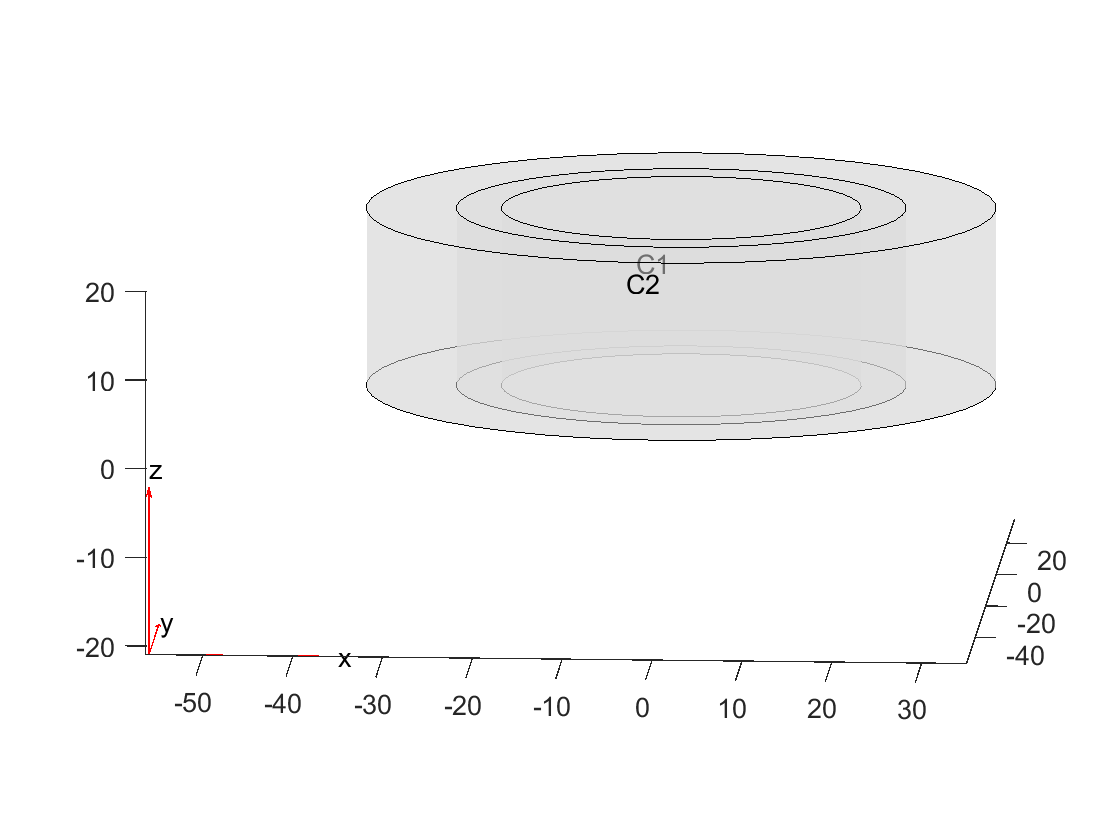

thermalmodel = createpde('thermal','transient');
g = decsg([3 4 -1.5 1.5 1.5 -1.5 0 0 .2 .2]');
geometryFromEdges(thermalmodel,g);
thermalmodel.Geometry = geom;
pdegplot(thermalmodel,'CellLabels','on','FaceAlpha',0.5);

Specify the thermal conductivity as a linear function of temperature, *k*=40+0.003*T*. 

`【state.u` — Temperatures at the corresponding points of the location structure】

【`location.y` — The *y*-coordinate of the point or points】

k = @(location,state)40 + 0.003*state.u;

Specify the specific heat as a linear function of the *y-*coordinate, *cp*=500*y*.

cp = @(location,state)500*location.y;

Specify the thermal conductivity, mass density, and specific heat of the material.

thermalProperties(thermalmodel,'ThermalConductivity',k,...
                               'MassDensity',2.7*10^(-6),...
                               'SpecificHeat',cp)

ans =   ThermalMaterialAssignment - 属性:

             RegionType: 'cell'
               RegionID: [1 2]
    ThermalConductivity: @(location,state)40+0.003*state.u
            MassDensity: 2.7000e-06
           SpecificHeat: @(location,state)500*location.y


【注意】：`RegionType`** — Geometric region type：**`'Face'` for a 2-D model | `'Cell'` for a 3-D model